## AAE 334 LAB 1 MATLAB CODE: AUTHOR TOMOKI KOIKE

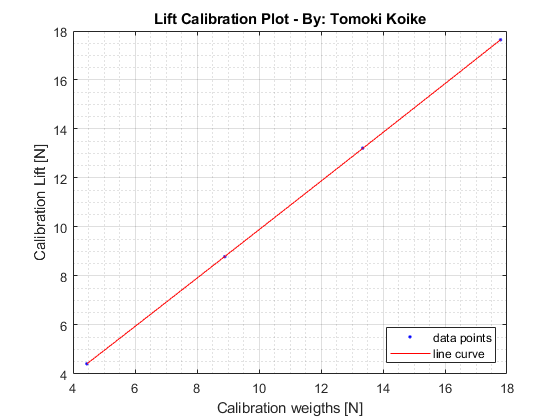

clear all; close all; clc

% Calibration 
% Reading the calibration data file as a matrix 
calib_data = readmatrix('calib.xlsx');

% Assigning variables to the data 
lift_weights = lbs2newton(calib_data(6:9,2));  % weights for the lift [N]
lift_calib = -lbs2newton(calib_data(6:9,3));  % calibration lifts [N]

% Fitting data calibration data
[fitresult gof] = createFit(lift_weights, lift_calib);

disp(fitresult);

     Linear model Poly2:
     fitresult(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =   0.0007022  (-0.003834, 0.005238)
       p2 =      0.9757  (0.8732, 1.078)
       p3 =     0.06181  (-0.4379, 0.5616)


coeffs = coeffvalues(fitresult);  % Obtaining the coefficients
% Assigning the coefficients for the fitted curve 
c1 = coeffs(1);
c2 = coeffs(2);
c3 = coeffs(3); 
% Defining a equation expression for lift scaling
syms lift
scale_lift = @(lift) c1*lift.^2 + c2*lift + c3;

% Reading the data for the airfoils 
lift_data = readmatrix('airfoil_lifts.xlsx');
% Assigning the lift data for each airfoil (scaling simultaneously)
airfoil1 = scale_lift(lbs2newton(lift_data(1:14)));
airfoil2 = scale_lift(lbs2newton(lift_data(16:32)));
airfoil3 = scale_lift(lbs2newton(lift_data(34:48)));
% Creating vectors for each airfoils containing the angle of attacks 
AoA_1 = 0:length(airfoil1)-1;
AoA_2 = 0:length(airfoil2)-1;
AoA_3 = 0:length(airfoil3)-1;

% Calculate lift coeffs 
airfoil1 = cal_liftcoeff(airfoil1);
airfoil2 = cal_liftcoeff(airfoil2);
airfoil3 = cal_liftcoeff(airfoil3);

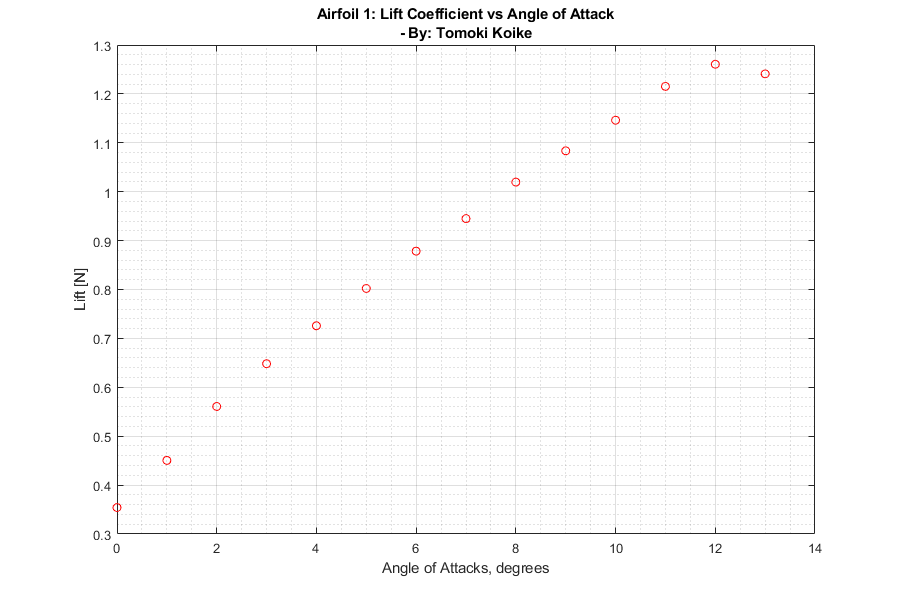

% Plotting
fig1 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plot(AoA_1, airfoil1, 'or')
title({'Airfoil 1: Lift Coefficient vs Angle of Attack', ...
    '- By: Tomoki Koike'})
xlabel('Angle of Attacks, degrees')
ylabel('Lift [N]')
xlim([0, 14])
grid on 
grid minor 
box on 
saveas(fig1, 'lift_curve.png')

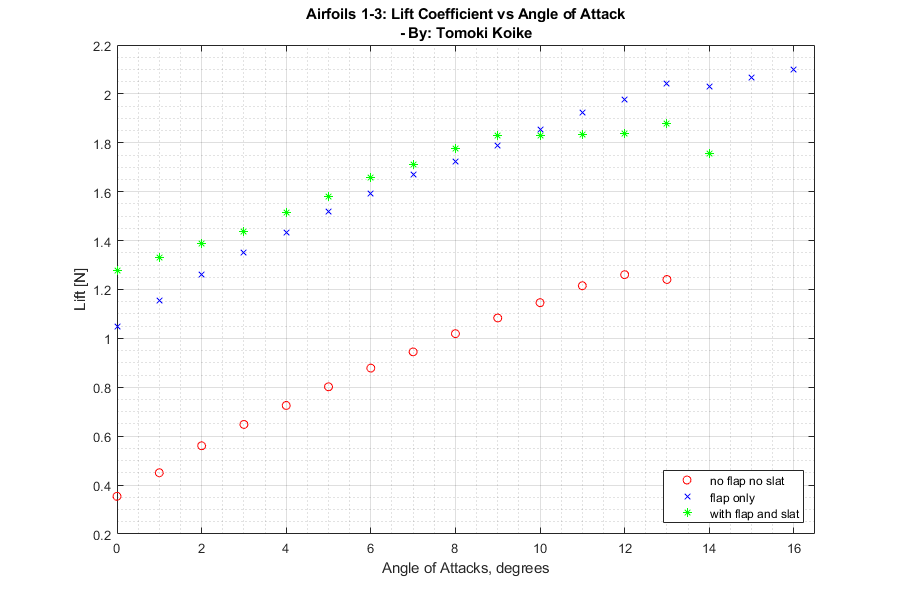


fig2 = figure('Renderer', 'painters', 'Position', [10 10 900 600]);
plot(AoA_1, airfoil1, 'or')
title({'Airfoils 1-3: Lift Coefficient vs Angle of Attack', ...
    '- By: Tomoki Koike'})
xlabel('Angle of Attacks, degrees')
ylabel('Lift [N]')
hold on 
plot(AoA_2, airfoil2, 'xb')
plot(AoA_3, airfoil3, '*g')
hold off 
xlim([0, 16.5])
grid on 
grid minor 
box on 
legend('no flap no slat', 'flap only', 'with flap and slat', ...
    'location', 'southeast')
saveas(fig2, 'lift_curve_all.png')

function N = lbs2newton(w)
    % Function that converts lbs to Newtons
    N = w*4.44822; 
end

function [fitresult, gof] = createFit(lift_weights, lift_calib)
    %CREATEFIT(LIFT_WEIGHTS,LIFT_CALIB)
    %  Create a fit.
    %
    %  Data for 'draf calib' fit:
    %      X Input : lift_weights
    %      Y Output: lift_calib
    %  Output:
    %      fitresult : a fit object representing the fit.
    %      gof : structure with goodness-of fit info.
    %
    %  See also FIT, CFIT, SFIT.
    %% Fit: 'draf calib'.
    [xData, yData] = prepareCurveData( lift_weights, lift_calib );
    
    % Set up fittype and options.
    ft = fittype( 'poly2' );
    opts = fitoptions('Method', 'LinearLeastSquares' );
    opts.Robust = 'Bisquare';
    
    % Fit model to data.
    [fitresult, gof] = fit( xData, yData, ft, opts );
    
    % Plot fit with data.
    figure( 'Name', 'draf calib' );
    h = plot( fitresult, xData, yData );
    % Label axes
    title('Lift Calibration Plot - By: Tomoki Koike')
    xlabel( 'Calibration weigths [N]', 'Interpreter', 'none' );
    ylabel( 'Calibration Lift [N]', 'Interpreter', 'none' );
    legend('data points', 'line curve', 'Location', 'southeast')
    grid on
    grid minor 
    box on
end 

function C_l = cal_liftcoeff(L)
    rho = 1.225;  % Desity of air at standard condition [kg/m^3]
    vel = 19.6;  % Velocity at 30Hz [m/s]
    q = 0.5*rho*vel^2;
    b = 0.2921;  % wing span [m]
    c = 3.75/39.37;  % Chord length [m]
    C_l = L / q / c / b;
end